clc,close,clear


simout = sim('sbw_actuator_new260308_forsim.slx')


Use vehicle solver: D:\Tools\Extensions\Carsim2020\CarSim2020.0_Prog\Programs\solvers\carsim_64.dll
CarSim 2020.0
Vehicle Configuration: I_I
Revision 125462, December 17, 2019

SBW_actuator_validation_sp_simu <Insight_SystemDynamics>

Termination at simulation time = 10 s.
Computational time ratio: 2.0442 (real time)/(simulation time)




simout =   Simulink.SimulationOutput:

                   tout: [100001x1 double] 
                x_r_car: [100001x1 double] 
               x_sr_car: [100001x1 double] 
               x_sr_sim: [100001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



% sim = out

carout = sim('sbw_actuator_new260308_forCar.slx')


Use vehicle solver: D:\Tools\Extensions\Carsim2020\CarSim2020.0_Prog\Programs\solvers\carsim_64.dll
CarSim 2020.0
Vehicle Configuration: I_I
Revision 125462, December 17, 2019

SBW_actuator_validation_sp_car <Insight_SystemDynamics>

Termination at simulation time = 10 s.
Computational time ratio: 1.6325 (real time)/(simulation time)




carout =   Simulink.SimulationOutput:

                   tout: [100001x1 double] 
                x_r_car: [100001x1 double] 
               x_sr_car: [100001x1 double] 
               x_sr_sim: [100001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



% car = out

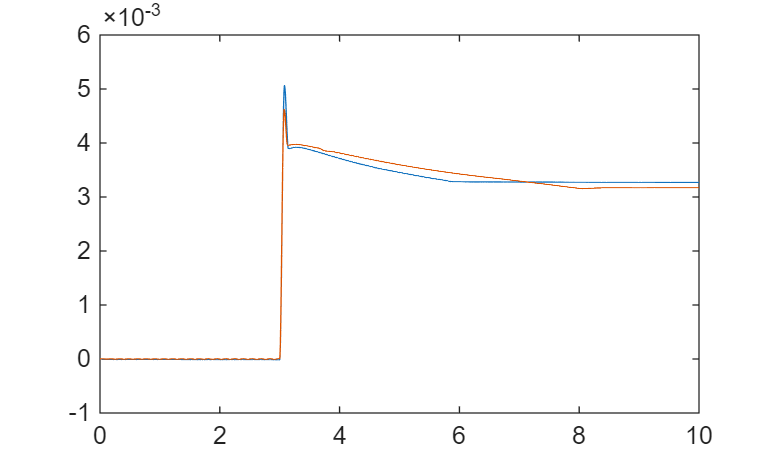


figure
plot(simout.tout,simout.x_sr_sim)
hold on
plot(carout.tout,carout.x_sr_car)

simout = out

simout =   Simulink.SimulationOutput:

                   tout: [100001x1 double] 
                x_r_car: [100001x1 double] 
               x_sr_sim: [100001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


carout = out

carout =   Simulink.SimulationOutput:

                   tout: [100001x1 double] 
                x_r_car: [100001x1 double] 
               x_sr_sim: [100001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


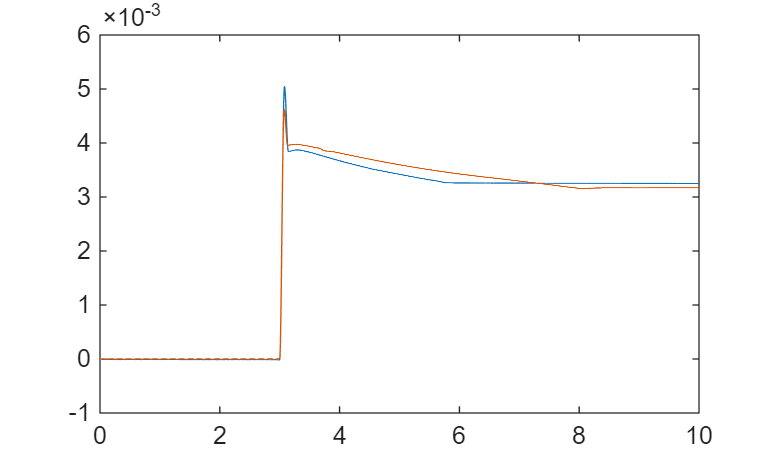

figure
plot(simout.tout,simout.x_sr_sim)
hold on
plot(carout.tout,carout.x_r_car)